# Autophosphorylation Switch: Modulation by Phosphatase Activity

The kinase activates itself and is antagonized by a phophatase. *x* is the fraction of kinase in the active (phosphorylated) state.

## 
$${\frac{dx}{dt}}=\dot{x}=f(x)=K(1-x)({\frac{x^n}{x^n+x_M^n}}+0.1)-Px$$


## Script to make the increasing and decreasing rates

K = 1;    %maximum kinase activity
n = 6;    %cooperativity
xM = 0.2; %concentration for half-maximum oligomerization
P = 2;    %phosphatase activity

## Question a(i): plot phosphorylation (green) and dephosphorylation (red) rates 

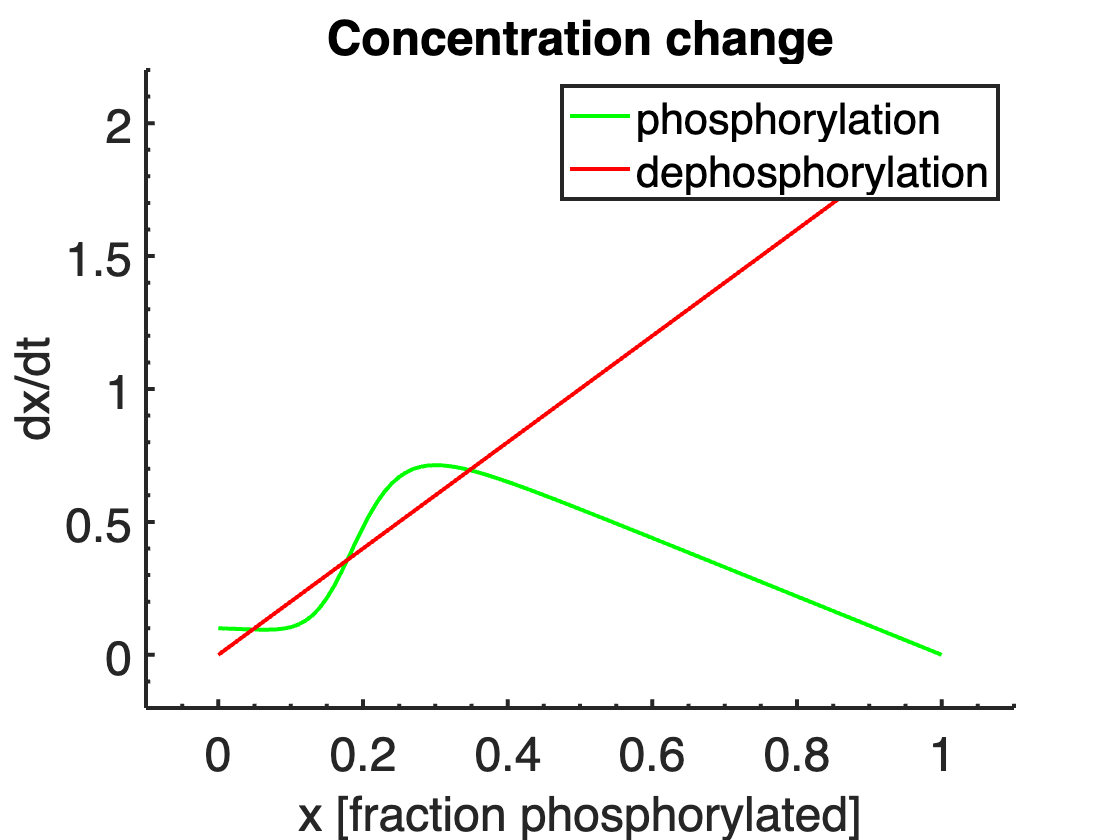

xa = 0:.01:1;  %array of x values
figure; hold on;
% plot the increasing rate in green
dx_increase = K.*(1 - xa).*(((xa.^n)./(xa.^n + xM^n))+0.1);
plot(xa, dx_increase, 'g-');
% plot the decreasing rate in red;
dx_decrease = P*xa;
plot(xa, dx_decrease, 'r-');
% set plot parameters.
title('Concentration change');
xlabel('x [fraction phosphorylated]');
ylabel('dx/dt');
legend('phosphorylation','dephosphorylation');
PrettyFig;

## Question a(ii): plot of a bunch of decay rates

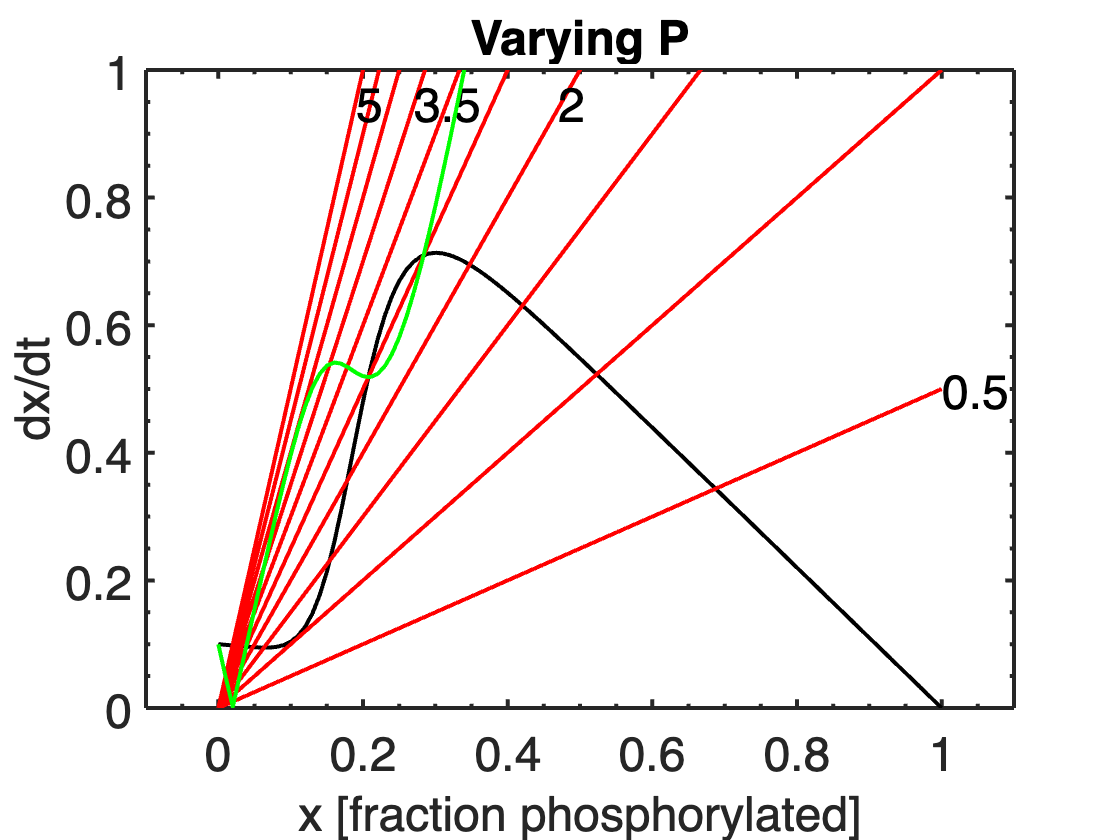

Parray = 0.5:0.5:5;
figure; hold on; clf; zoom on;

%plot the phosphorylation (increasing) curve in black)
dx_increase = K.*(1 - xa).*(((xa.^n)./(xa.^n + xM^n))+0.1);
plot(xa, dx_increase, 'k-');
hold on;

%Plot the dephosphorylation curves for each element of the Parray
for k=1:length(Parray)
    P = Parray(k);
    dx_decrease = P * xa;
    plot(xa, dx_decrease, 'r-');

    if(P==5)
    plot(xa, abs(dx_decrease-dx_increase), 'g-');
    end

    % find x index at y=1.
    [discard, xBoundIdx] = min(abs(dx_decrease-0.95));
    xBound = xa(xBoundIdx);

    % display P values.
    if((k-1)/3 == round((k-1)/3))
        text(xBound, min([0.95, dx_decrease(end)]), num2str(P))
    end
end

set(gca,'ylim',[0 1]);
xlabel('x [fraction phosphorylated]');
ylabel('dx/dt');
title('Varying P');
PrettyFig;

## Question a(iii) What are the two approximate values of P where the number of fixed points changes

At lower values of P, there is only *one fixed point*. At about **P = 1**, there are *two fixed points*, when the dephophorylation rate curve "kisses" the phosphorylation curve at a lower x value. Beyond this value of P, there are *three fixed points*.

At a little higher than **P = 2.5**, the system goes back to *two fixed points, *where the curves "kiss" at a higher x value. Beyond this value of P, there is again only *one fixed point.*

Hence, the number of fixed points changes at **P = 1** and a little over** P = 2.5**, from one to three and three to one fixed points, respectively. (Based on the plot in question (b)(ii), the second value of P is close to **2.69**).

## Question b(i): You need to rearrange the equation so P(x*) =  and put it into the code below

Numerical solution included in writeup.

## Question b(ii): solution for fixed points x* vs. P

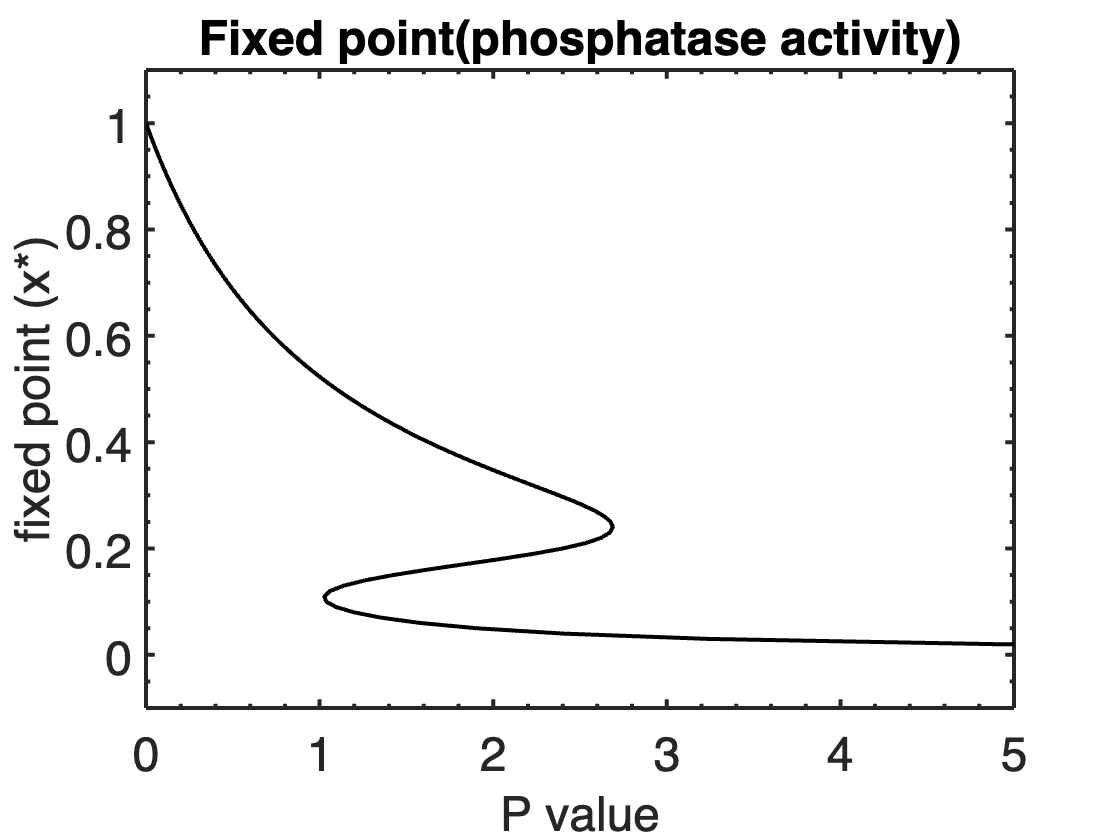

xa = 0:.01:1;
% this line of code answers b(i)
Psolve = K.*((1 - xa)./xa).*(((xa.^n)./(xa.^n + xM^n))+0.1);
figure; zoom on;
%plotPsolve on the x-axis, x* on the y-axis
plot(Psolve, xa, "k-");
xlabel('P value');
ylabel('fixed point (x*)');
title('Fixed point(phosphatase activity)');
set(gca,'xlim',[0 5]);
PrettyFig;

## c(i): What are the approximate values of the critical points for P? Answer here ...

The critical values of P at which the system undergoes fast transitions are at:

(1) About **P = 2.69**, when the system switches from the higher values of fixed points to the lower ones as P increases.  

(2) About **P = 1**, when the system switches from the lower values of fixed points to the higher ones as P decreases.

## c(ii): Add arrows

Arrows added.

## **c(iii):** Describe in words how this plot shows hysteresis. Answer here ...

The *black* and *red* arrows show the approximate trajectories of the fixed point, x*(T), as P *increases* and *decreases*, respectively. 

As P increases from 0.5 to 5 slowly over time, allowing the system to reach equilibrium every step of the way, x*(T) moves along the upper curve of stable fixed points. Once P crosses its critical value of **P = 2.69 **and moveed toward 5, x*(T) jumps to the lower curve of stable fixed points. However, when P decreases again from P, x*(T) continues to stay on the lower curve of fixed points, even after P cross the critical value of 2.69. 

As P continues to decrease toward 0.5, x*(T) jumps to the upper curve of fixed points again when the P value reaches the lower critical value of **P = 1**. It stays on this curve as P decreases. If P starts to increase again, x*(T) stays on the upper curve until **P = 2.69**.

Hence, the system switches from the "high" to "low" state when P is increasing in the "high" state and reaches **P = 2.69 **(the black arrow trajectory). It switches back from "low" to "high" state when P is decreasing in the "low" state and reaches **P = 1 **(the red arrow trajectory).

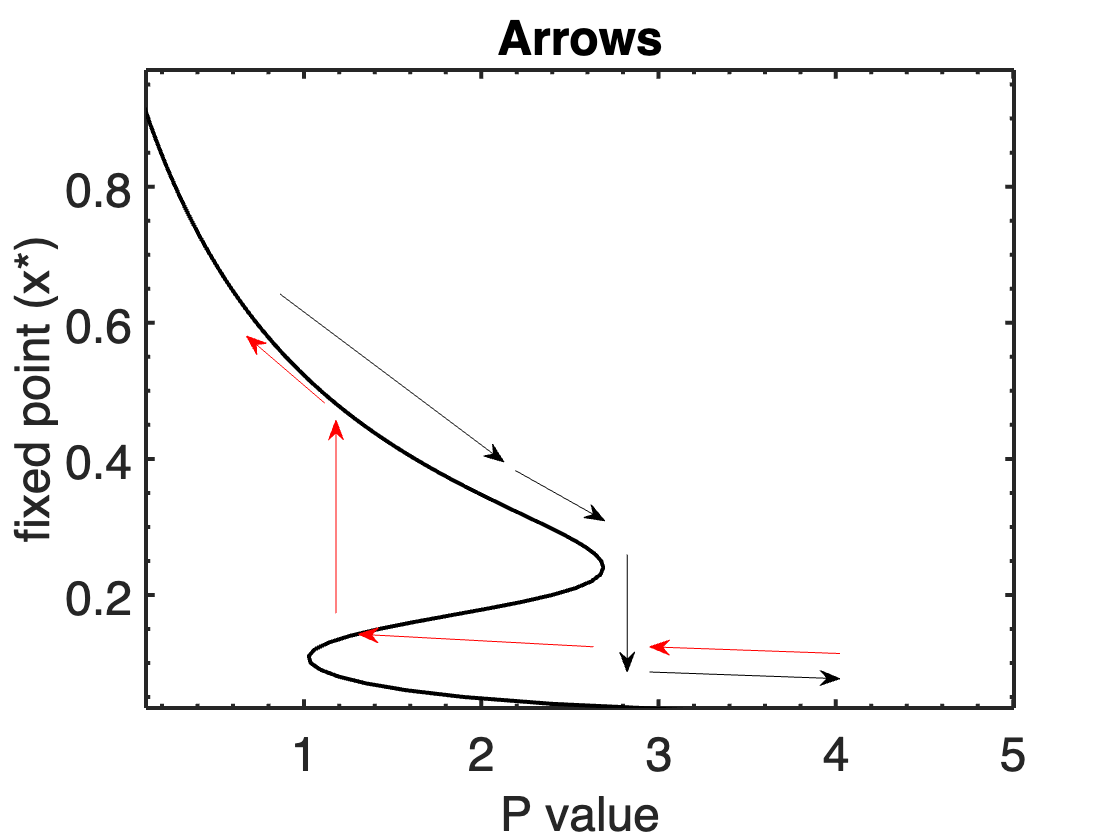

% adding arrows
figure; zoom on;
%plot xa vs Psolve again
plot(Psolve, xa, "k-");
xlabel('P value');
ylabel('fixed point (x*)');
set(gca,'xlim',[0 5]);
title('Arrows');
hold on;
%here is one arrow
% TRANSITION 1 (increasing).
annotation('textarrow',[.25 .45],[.65 .45]);
annotation('textarrow',[.46 .54],[.44 .38]);
annotation('textarrow',[.56 .56],[.34 .20]);
annotation('textarrow',[.58 .75],[.20 .192]);
% TRANSITION 2 (decreasing).
annotation('textarrow',[.75 .58],[.222 .23], 'Color', 'red');
annotation('textarrow',[.53 .32],[.23 .245], 'Color', 'red');
annotation('textarrow',[.30 .30],[.27 .50], 'Color', 'red');
annotation('textarrow',[.29 .22],[.52 .60], 'Color', 'red');
%add the other arrows
set(gca,'ylim',[0 1]);
PrettyFig;

## d(i): do a ton of integrations to get the fixed points by method in (a)

this is the hard part!!

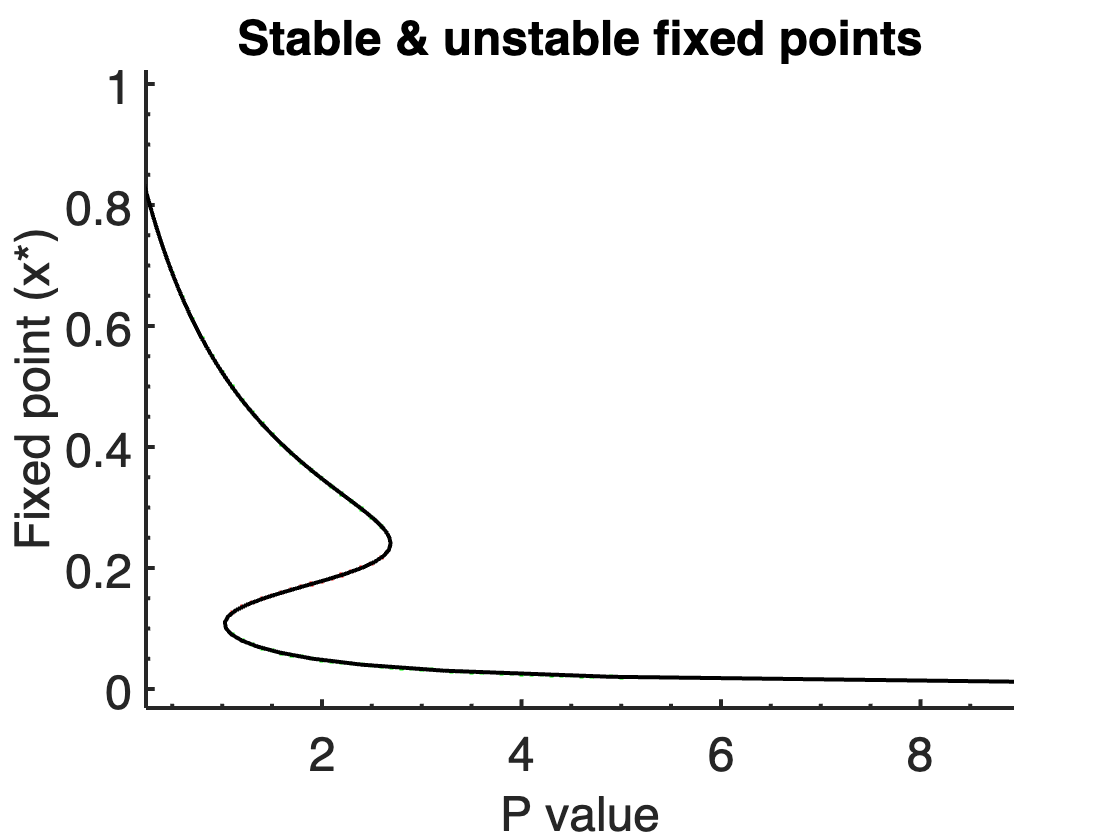

xstart = [0:0.05:1]; %starting values of x
Pchoose = [0.5:0.1:5]; %Values of phosphatase activity

Tend = 15.0; %Final time (may not be long enough)
% This is set within the loop, again.

figure; hold on; zoom on;
%plot the fixed-point curve again in black.
%you are going to cycle through all the P values.
for ii=1:length(Pchoose) 
    
    P = Pchoose(ii);
    for jj=1:length(xstart) % for each P value solve the ODE.
    
        % set a different Tend for forwards ODE.
        Tend = 15;
        % here is the
        % ode45 code - just an an expression for dx/dt
        [tout, xout] = ode45(@(t,x) differential_equation(t, x, K, P, xM, n), ...
            [0.0 Tend], xstart(jj));
   
        % plot the last point of xout in green;
        plot(P, xout(end), 'g.');
    
        %d(iii) delineate the unstable region on the P axis 
        %d(iii) Pmin=??;Pmax=??
        Pmin = 1.00;
        Pmax = 2.80;
        %d(iii) note you have to have xstart in the unstable region as well 
        %d(iii) xstartmin=??;xstartmax=??;
        xstartmin = 0.10;
        xstartmax = 0.28;
        %% The min and max values are set such that they encroach slightly into the
        %%  stable region so that no points in the unstable region is missed.
        % set a different Tend for backwards ODE.
        Tend = 80;
        %d(iii) if your are in the unstable region then run the ode backwards
        %d(iii) if ...
        if(xstart(jj)>=xstartmin && xstart(jj)<=xstartmax)

            %d(iii) run time backwards in ode45 by putting dx/dt(-t) = -dx/dt (i.e. solve dx/dt=-f(x)
            [tout, xout] = ode45(@(t,x) differential_equation_reverse(t, x, K, P, xM, n), ...
                [0.0 Tend], xstart(jj));

            %d(iii) plot the the last point of xout in red
            plot(P, xout(end), 'r.', 'LineWidth', 6);
        end
    end
    % plot analytical solution for reference.
    Psolve = K.*((1 - xa)./xa).*(((xa.^n)./(xa.^n + xM^n))+0.1);
    plot(Psolve, xa, 'k-', 'LineWidth', 0.1);
end
% set(gca, 'xlim',[0 5], 'ylim', [0 1]);
xlabel('P value');
ylabel('Fixed point (x*)');
title('Stable & unstable fixed points');
PrettyFig;

## d(ii) Why are some points not on the line? What if you change the final time

## d(iii): find unstable fixed points by adding code in the indicated area above

## e(i) now, plot up the contour method (graduate student question)

use the surf function to plot the surface with xarray on the x-axis, Parray on the y-axis and dx/dt on the z-axis

use the contour function to plot a section through 

[xarray,Parray]=meshgrid(xa,Pchoose);
%plot dx/dt on the mesh and plot the surface
xlabel('x');
ylabel('P');
zlabel('dx/dt');
PrettyFig;

figure; hold on;
set(gca,'xlim',[0 5],'ylim',[0 1]);
%now plot the contour
xlabel('P');
ylabel('x*');
title('Fixed points as a function of P');
PrettyFig;